# Finite Solid Primitives usage example

#### Common setup for all examples

ex_setup

Setup complete


#### Start timer

tic

#### Povlab object

pl = povlab( povray_version,...
             povray_path, ...
             povray_out_dir);

#### Scene

pl.scene_begin('scene_file', 'primitives.pov', 'image_file', 'primitives.png');
    pl.include("shapes");
    
    pl.global_settings("assumed_gamma 1");

    %%%%%%%%%%%%%%%%%%%%%%%%%
    pl.axis();

    % Camera
    pl.camera('angle', 35, 'location', [28 15 10], 'look_at', [0 6 3.5], 'type', 'perspective');
    
    % Lights
    pl.light('location', [100 100 300], 'color', [0.4 0.4 0.4], 'shadowless', false);
    pl.light('location', [10 4 3], 'color', [0.2 0.2 0.2], 'shadowless', true);
    
    % Walls
    tex_plane = pl.declare("tex_plane",   pl.texture('pigment_odd', [1.5 1.5 1.5], 'pigment_even', [0.1 0.1 0.1], 'finish', "phong 1 reflection {0.05 metallic 0.4}"));    
    pl.plane('normal', [1,0,0], 'distance', -10, 'texture', tex_plane', 'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 1]);
    pl.plane('normal', [0,0,1], 'distance', 0, 'texture', tex_plane', 'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
    
    % Textures
    tex_red   = pl.declare("tex_red",   pl.texture('pigment', [1 0 0], 'finish', 'phong 1 reflection {0.10 metallic 0.4}'));
    tex_green = pl.declare("tex_green", pl.texture('pigment', [0 1 0], 'finish', 'phong 1 reflection {0.10 metallic 0.4}'));
    tex_blue  = pl.declare("tex_blue",  pl.texture('pigment', [0 0 1], 'finish', 'phong 1 reflection {0.10 metallic 0.4}'));
    tex_pink  = pl.declare("tex_pink",  pl.texture('pigment', [8 2 3], 'finish', 'phong 1 reflection {0.10 metallic 0.4}'));

    % Objects
    pl.box('llf_corner', [0 0 0], 'urb_corner', [1 1 1] , 'texture', tex_red);
    pl.sphere('position', [0 4 2], 'radius', 2, 'texture', tex_red);    
    pl.cylinder('base_point', [0 8 0], 'cap_point', [0 8 5], 'radius', 1.5, 'texture', tex_green);
    pl.cone('base_point', [0 12 0], 'base_radius', 1.5, 'cap_point', [0 12 5], 'cap_radius', 0.5, 'texture', tex_blue);
    pl.cone('base_point', [0 16 0], 'base_radius', 1.5, 'cap_point', [0 16 5], 'texture', tex_pink);

pl.scene_end();

#### Render and display

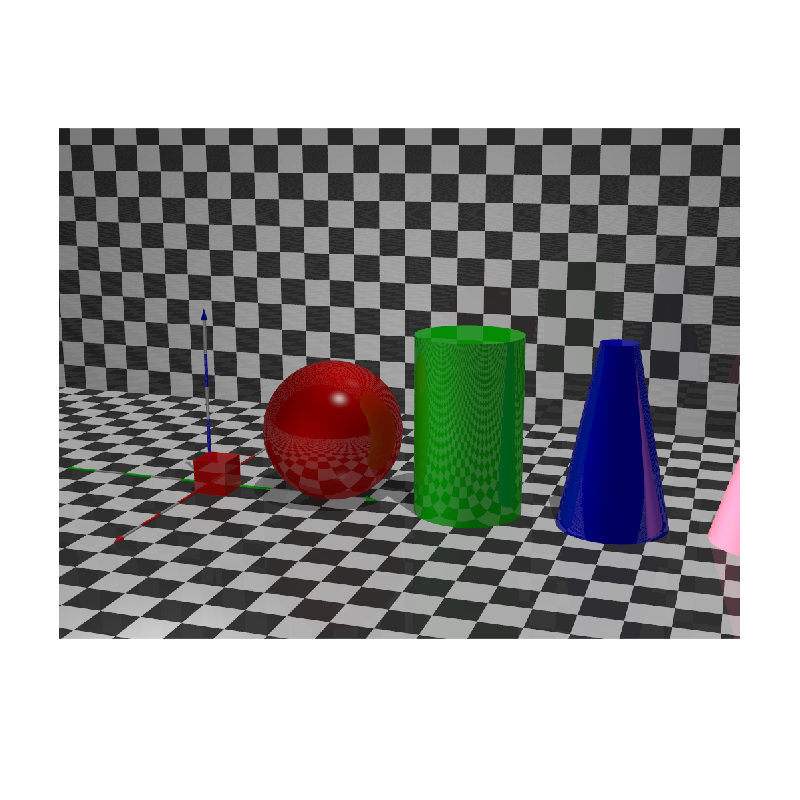

img = pl.render();
imshow(img);

#### Elapsed time

toc

Elapsed time is 4.594109 seconds.
